clear all
clf

%The following path has to be adjusted for each computer!!!!!
source_dir = 'D:/A_Karos Kram/Studium England/Year2/MAPS2001/1project/MATLAB-Isotopes-master/MATLAB-Isotopes-master/MakingMaps/'

source_dir = 'D:/A_Karos Kram/Studium England/Year2/MAPS2001/1project/MATLAB-Isotopes-master/MATLAB-Isotopes-master/MakingMaps/'


%Load all .xls files (the climate data) into one cell array
source_files = dir(fullfile(source_dir, '*.xls'));
AATdata=cell(size(source_files));

for i = 1:length(source_files)
  AATdata{i} = readtable(fullfile(source_dir, source_files(i).name));
end

%Load all .xlsx files (the Isotope data) into one cell array
moresource_files = dir(fullfile(source_dir,'*.xlsx'));
Isotopedata=cell(size(moresource_files));
for j = 1:length(moresource_files)
  Isotopedata{j} = readtable(fullfile(source_dir, moresource_files(j).name));
end



%Calculate the means and medians for H2, H3, O18 and Temperature across all datasets
means=zeros(size(Isotopedata,1),4); %creates arrays full of zeros of the right size
medians=zeros(size(Isotopedata,1),4);

for i= 1:length(Isotopedata)
    
   activedata=Isotopedata{i,1};                    
   tempdata=AATdata{i,1};
   
   means(i,1)=mean(activedata.H2, 'omitnan');       %Means for the isotopes
   means(i,2)=mean(activedata.H3, 'omitnan');
   means(i,3)=mean(activedata.O18, 'omitnan');
                                                
   medians(i,1)=median(activedata.H2, 'omitnan');   %Medians for the Isotopes
   medians(i,2)=median(activedata.H3, 'omitnan');
   medians(i,3)=median(activedata.O18, 'omitnan');
                    
   means(i,4)=mean(tempdata.tas, 'omitnan');        %Means for temperatures
    
   medians(i,4)=median(tempdata.tas, 'omitnan');    %Medians for temperatures
   
end  


According to the  reference *G. Torri, D. Ma, Z. Kuang Stable water isotopes and large-scale vertical motions in the tropics, Journal of Geophysical Research: Atmospheres Volume 122, Issue 7, pages 3703-3717, 2017 *on page 3707, the abundance of deuterium is measured with the following formula:


$$\delta D=\left(\frac{R_{\mathrm{sample}} }{R_{\mathrm{VSMOW}} }-1\right)\cdot 1000\text{ }‰$$


where:

$R_{\mathrm{sample}}$ is the ratio of deuterium to the common, stable isotope of hydrogen in the samples considered,

 $R_{\mathrm{VSMOW}}$ is the same ratio but for a reference sample with the isotopic composition of the Vienna standard mean ocean water.


$$R_{\text{VSMOW}} =155\ldotp 76\pm 0\ldotp 1ppm$$
 


% The H3 abundance is not given in Delta D, but in TU (Tritium atoms per 1018 Hydrogen atoms), so Delta D must be calculated:
vsmow=1.85*10^-11;   %Given in ppm 
means(:,2)=((means(:,2).*(1/1018)./vsmow)-1).*1000

means =    1.0e+13 *

   -0.0000    1.4455   -0.0000    0.0000
   -0.0000    0.1527   -0.0000    0.0000
   -0.0000    0.1274   -0.0000    0.0000
   -0.0000    0.0488   -0.0000    0.0000
   -0.0000    0.1019   -0.0000    0.0000
   -0.0000    0.8573   -0.0000    0.0000
    0.0000    0.5464    0.0000    0.0000
   -0.0000    0.0215   -0.0000    0.0000
   -0.0000    0.0637   -0.0000    0.0000
   -0.0000    0.2045   -0.0000    0.0000


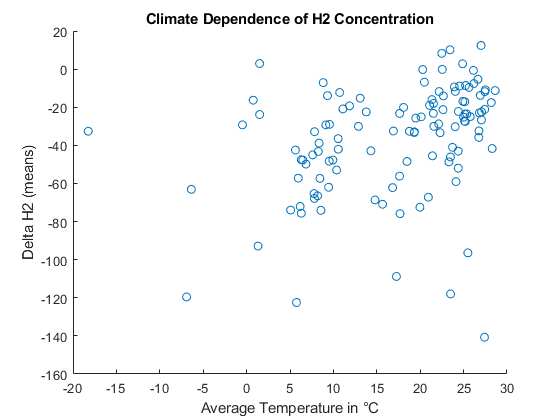

medians(:,2)=((medians(:,2).*(1/1018)./vsmow)-1).*1000;


%Plot scatterplots of isotope concentration in precipitation vs temperature

scatter(means(:,4),means(:,1));     %H2 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (means)');
title('Climate Dependence of H2 Concentration');

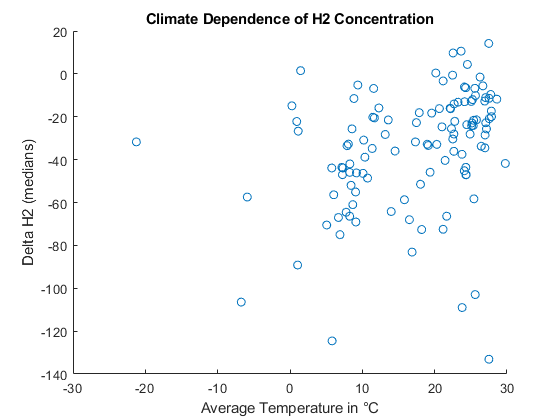


scatter(medians(:,4),medians(:,1));     %H2 median values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (medians)');
title('Climate Dependence of H2 Concentration');

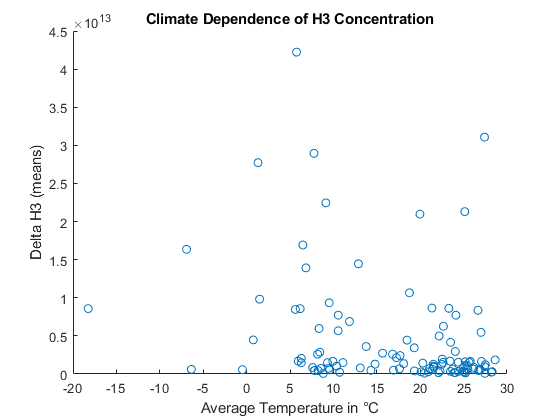


scatter(means(:,4),means(:,2));     %H3 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (means)');
title('Climate Dependence of H3 Concentration');

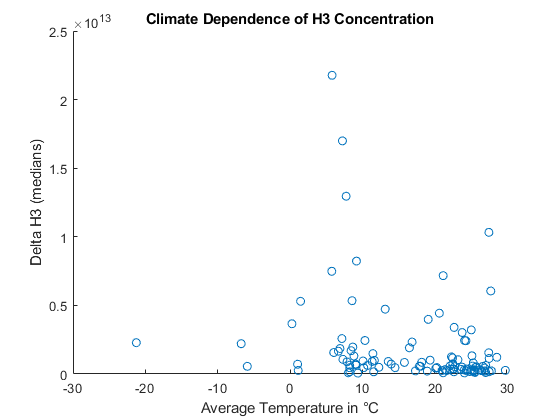


scatter(medians(:,4),medians(:,2));     %H3 median values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (medians)');
title('Climate Dependence of H3 Concentration');

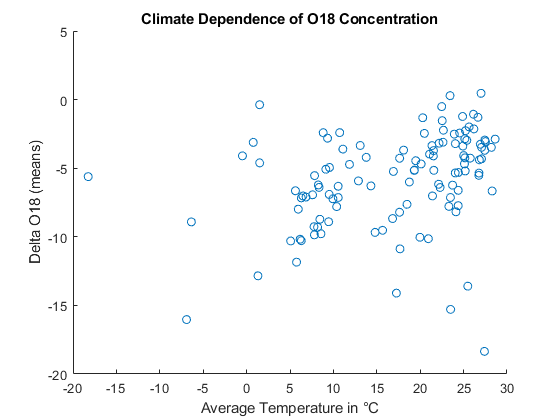


scatter(means(:,4),means(:,3));     %O18 mean values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (means)');
title('Climate Dependence of O18 Concentration');

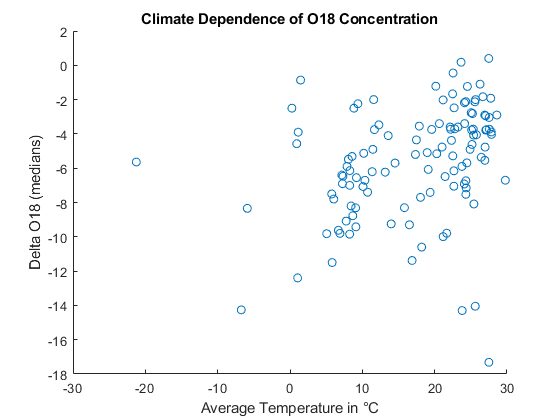


scatter(medians(:,4),medians(:,3));     %O18 median values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (medians)');
title('Climate Dependence of O18 Concentration');